%clear all
exp1 = load("exp1.txt");
time = exp1(:,1);
h_etalon = load("h_etalon.txt");

% Деклариране на промелнливите
global k T1 T2 tau k_vec T1_vec T2_vec %tau_vec
global orig optima op_st

orig = [time, h_etalon];

% Нулиране на боряча
op_st=0;
% въвеждане на примерни начални сойности
par = [5 10 10]

par =      5    10    10


% Дефинирае на условията
options=optimset('Display','Iter')

options = struct with fields:
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
     

%Стартиране на оптимизацията
par=lsqnonlin('er_mod', par,[],[], options)


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4         84755.6                      2.22e+04
     1          8          125.68             10            457      
     2         12         32.0302        8.16663            419      
     3         16        0.262876        1.33984             26      
     4         20       0.0425399        1.11952           1.94      
     5         24       0.0335379       0.197302         0.0796      
     6         28       0.0335294     0.00659287       8.73e-05      
     7         32       0.0335294    0.000109351       2.82e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

par =     1.0222    7.8383    4.7704


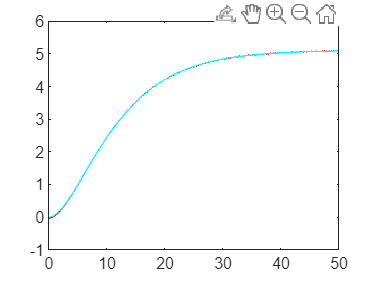

%Визуализиране на резултатите
figure(1), plot(orig(:,1), orig(:,2), 'r-', optima(:,1), optima(:,2), 'c-')

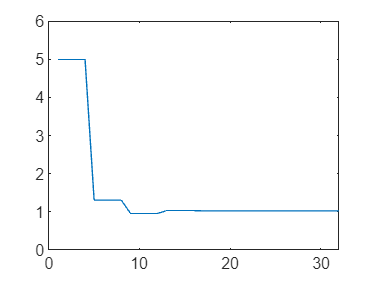

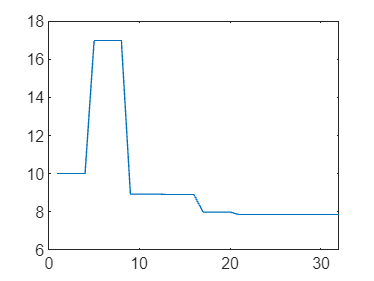

figure(2), plot(k_vec), figure(3), plot(T1_vec)

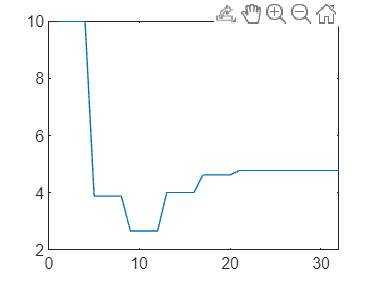

figure(4), plot(T2_vec), 

%figure(5), plot(tau_vec)